# Volume molaire partiel -- Volume de mélange

*Pascal Denis - Centrale Marseille*

*version 2 - 2021*

L'objectif de ce TD est de vous faire prendre conscience de la notion et de l'importance des volumes molaires partiels et des volumes de mélange, ainsi que des moyens permettant de les calculer.

## Aspect thermodynamique

Nous ne considérerons dans cette première approche que le cas mono-phasique d'un mélange de composés purs. Dans notre cas, nous prendrons un mélande gazeux de méthane et de propane. 

Pour estimer le volume du mélange, il est envisageable de prendre la rélation (1) 

$\displaystyle V_{total} = \sum_{1=1}^n N_i\cdot V_i $ (1)

$V_i $ désigne le volume molaire de l'espèce considérée comme si elle était seule. Cependant, il devrait vous paraître normal, que dans la majorité des cas nous ne puissions satisfaire la relation (1). Une contribution plus judicieuse de chaque espèce au volume totale est fournie par le volume molaire partiel, définie par : 

 $\bar{v}_i = \left (\frac{\partial V}{\partial N_i} \right )_{P,T,Nj\neq i}$(2) 

Et de part cette définition, on a : 

$\displaystyle dV = \left (\frac{\partial V}{\partial T} \right )_{P,Nj}dT + \left (\frac{\partial V}{\partial P} \right )_{T,Nj}dP + \sum_{i=1}^n \left (\frac{\partial V}{\partial N_i} \right )_{P,T,Nj\neq i}dN_i$ (3)   

On peut travailler en grandeur intensive, ou extensive avec les 2 relations suivantes, **à P et T constantes**, pour le volume totale  

$\displaystyle V = \sum_{i=1}^n N_i\cdot \bar{v}_i$ (4)

ou bien pour le volume molaire ($x_i$ désigne la fraction molaire)

$\displaystyle  v = \sum_{i=1}^n x_i\cdot \bar{v}_i$ (5)

Chacune des grandeurs molaires partielles tend vers deux données importantes : 

- la grandeur molaire de référence lorsque la fraction du composé tend vers l'unité. 

$\lim_{x_i \rightarrow 1}\bar{v}_i = v_i^{ref}$(6)

- la grandeur molaire à dilution infinie lorsque la fraction du composé tend vers zéro. 

$\lim_{x_i \rightarrow 0}\bar{v}_i = v_i^{\infty}$(7)

Dans le cas particulier d'un mélange idéal, on aura : 

$\displaystyle  v = \sum_{i=1}^n x_i\cdot {v_i}$ (8)

## Exemple d'application

On travaillera à partir d'un exemple issu de [1], à la pression de 1,377 MPa et à la température de 344,7 K, on a mesuré expérimentalement les  volumes molaires (${\textrm{cm}}^3 /\textrm{mol}$) en fonction de la fraction de méthane  : 

Les conditions de travail sont : 

P = 1377000; % Pression [Pa]
T = 344.7; % [K]

et les données expérimentales : 

% Titre en méthane
x = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
% Volume molaire expérimental dans les conditions T,P mentionnées ci-dessus.
V = [1748 1791 1835 1873 1910 1941 1967 1992 2016 2035 2047]; 

On prendra comme valeur numérique pour la constante des gaz parfait la valeur recommandée par [CODATA 2014](https://physics.nist.gov/cgi-bin/cuu/Value?r)

R = 8.314462618; % [J/mol.K] (valeur CODATA 2019)

#### Tracer la courbe du volume expérimental 

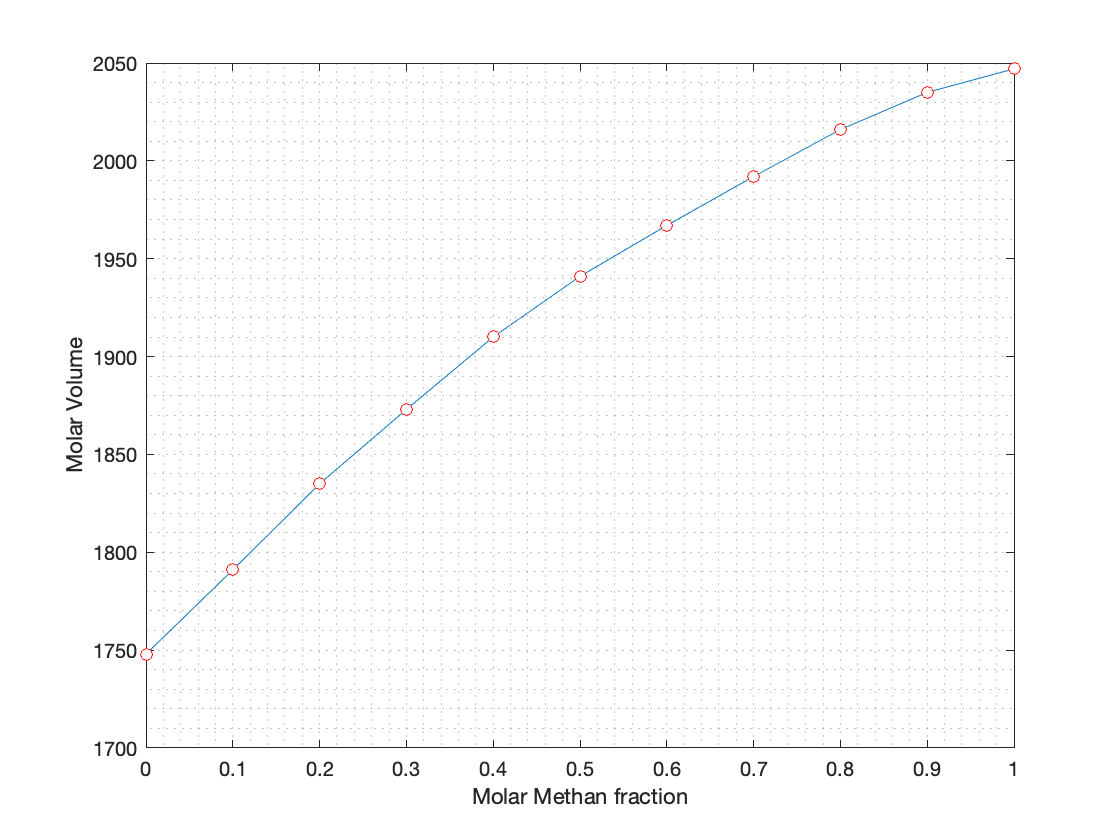


PLOT_EXP = plot(x, V,'-o', 'MarkerEdgeColor','r','MarkerFaceColor','w');
hold on;
xlabel('Molar Methan fraction');
ylabel('Molar Volume');
grid minor;

Quelles sont vos conclusions ? 

## Modèle thermodynamique du gaz parfait

Il est évident que pour x = 0.00 on a du propane pur, et pour x = 1 du méthane purOn a obtenu expérimentalement la valeur des volumes molaires du méthane et du propane purs, cependant il serait judicieux de faire un choix de modèle thermodynamique. Commençons par le gaz parfait et le méthane.

% Calcul du volume GP

V_GP = R*T/P * 1E6; % passage de m^3 à cm^3

Dans le cas du propane, on obtient : 


% Il n'y a aucune différence !

Tracer alors sur le graphe précédent le volume molaire du mélange en fonction du titre molaire. 

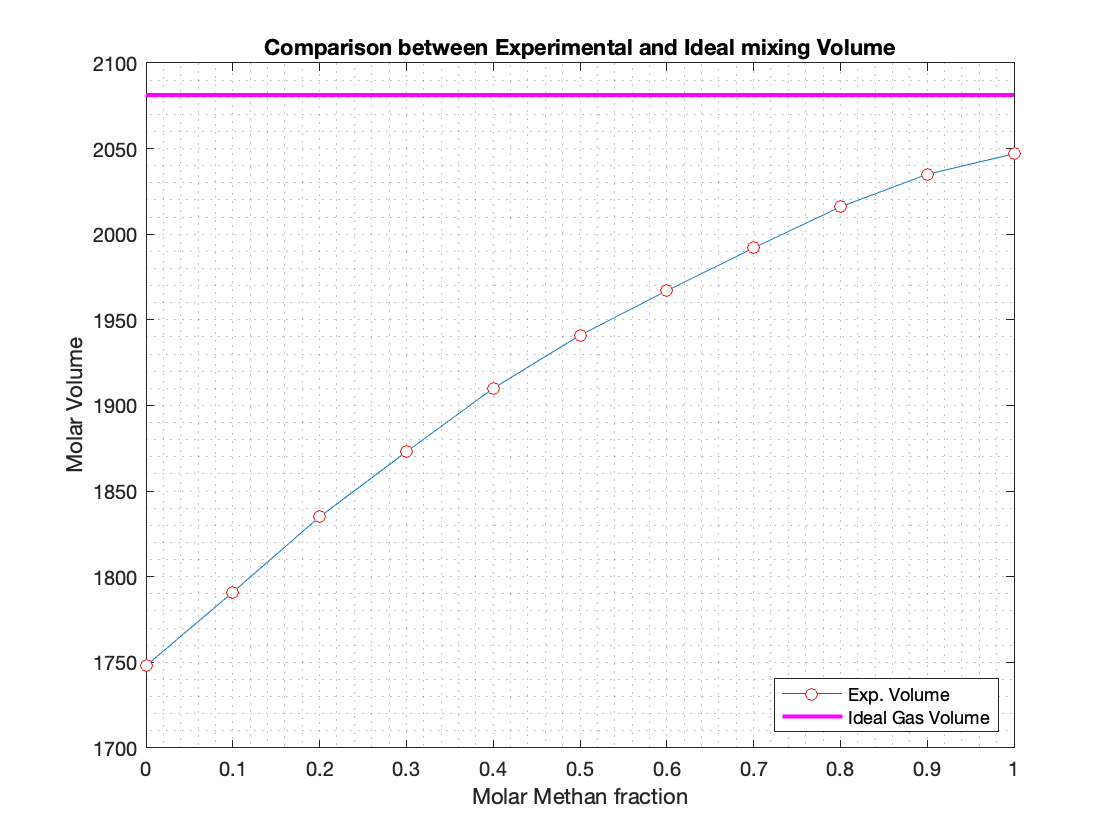

title('Comparison between Experimental and Ideal mixing Volume');
PLOT_GP = plot([0 1 ], [V_GP V_GP],'m', 'LineWidth',2);
legend({'Exp. Volume','Ideal Gas Volume'},'Location','southeast')
legend()
hold off

Quelle est votre conclusion ? 

## Equation d'état du Viriel

L'équation du viriel est définie simplement par (9), elles est plus simple à manipuler que les équations d'états cubiques,  mais plus limiter en pression et en température, mais aussi pour des molécules faiblement ou non polaires

$v = \frac{RT}{P}+ B(T)$ (9)

On obtiendra les données concernant le méthane et le propane dans [3, pp 6-48] [Virial Coefficient of selected gases](https://r3.vlereader.com/Reader?ean=9781498754293), ou si indisponible sur le PDF sous Moodle.

% Données du méthane  
T_Methane = [110 120 130 140 150 160 170 180 190 200 250 300 350 400 500 600]';
B_Methane_data = [-328 -276 -237 -206 -181 -160 -143 -128 -116 -105 -66 -43 -27 -16 0 10]';
C_Methane = [-43  -114 -19 -7];

Pour des raisons pratiques, il sera nécessaire soit de créer la fontion contenue dans [3], soit de faire du **curvefitting** pour trouver une "bonne fonction". 

Lancer l'application "Curve Fitting"

*N.B. il est aussi possible de passer par l'onglet Apps et sélectionner "Curve Fitting".*

Si le modèle d'interpolation est connu, alors on peut directement utiliser la fonction fit dans le script, comme ici  avec les modèles **polynomial, Exponential, rational, power, ou** **smoothingspline**. Comparer la fonction obtenue avec la fonction proposée par [3]. Quel est votre avis ? 

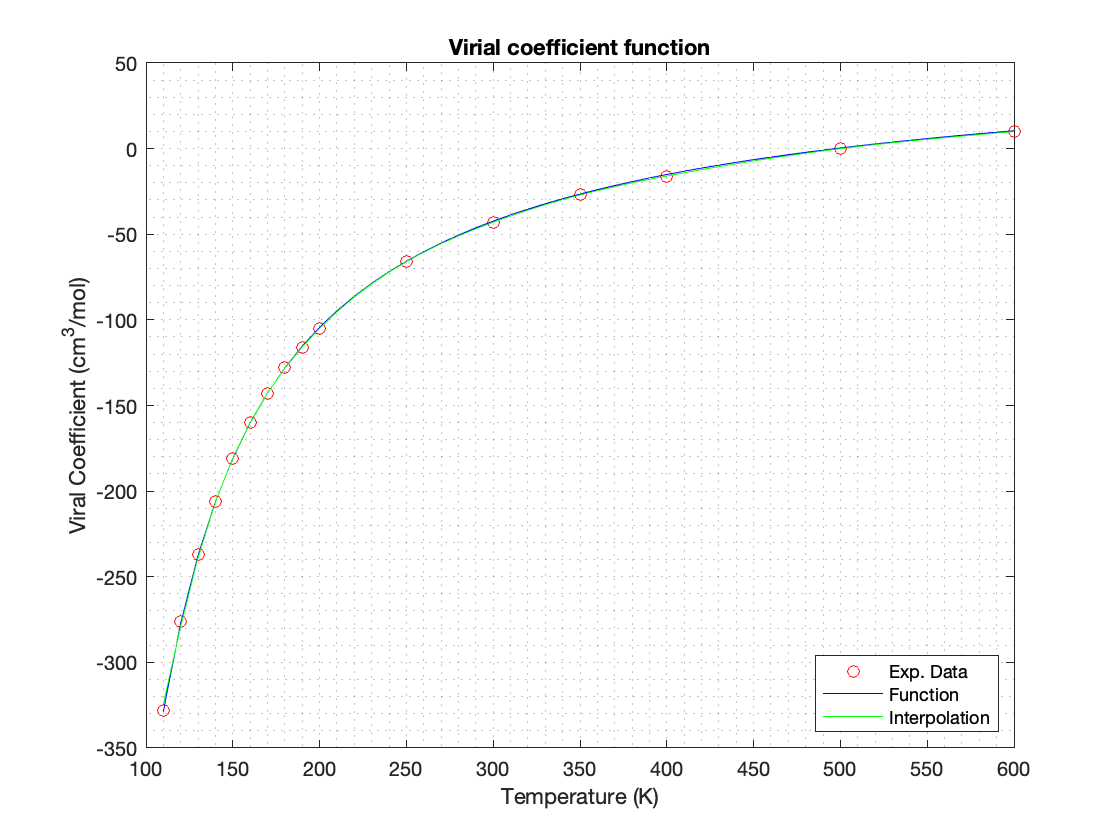

B_Methane = fit(T_Methane, B_Methane_data,'smoothingspline'); % c

% Vérification des coefficients et ajustement de la fonction

TT = T_Methane(1):10:T_Methane(end);
plot(T_Methane,B_Methane_data,'or') 
hold on 
plot(TT,Virial_B(TT,C_Methane),'b');
plot(TT,B_Methane(TT),'g');
grid minor
xlabel('Temperature (K)')
ylabel('Viral Coefficient (cm^3/mol)')
title('Virial coefficient function')
legend('Exp. Data','Function','Interpolation','location','southeast')
hold off




% Volume molaire du propane pour le fun ....
T_Propane = [240 260 280 300 320 340 360 380 400 440 480 520 560]';
B_Propane_data = [-641 -527 -444 -381 -331 -292 -259 -232 -208 -169 -138 -112 -90]';


Calculons désormais le volume molaire du méthane dans les conditions opératoires : 

% Calcul du Volume molaire du méthane
% Avec la fonction issue de [3]

B = Virial_B(T,C_Methane)/1000/1000; % Attention au changement d'unité
Z_Methane = 1 + B.*P./(R*T);
V_mol_Methane = R*Z_Methane.*T./P;

fprintf('Volume molaire Methane (Viriel) = %.2f cm3/mol \n',V_mol_Methane*1E6)

Volume molaire Methane (Viriel) = 2053.40 cm3/mol 


Calculons désormais le volume molaire du méthane dans les conditions opératoires : 


% Calcul du Volume molaire du propane
% Avec la fonction issue de [3]

C_Propane = [-386 -844 -720 -574];
B = Virial_B(T,C_Propane)/1000/1000; % Attention au changement d'unité
Z_Propane = 1 + B.*P./(R*T);
V_mol_Propane = R*Z_Propane.*T./P;

fprintf('Volume molaire Propane (Viriel) = %.2f cm3/mol \n',V_mol_Propane*1E6)

Volume molaire Propane (Viriel) = 1797.59 cm3/mol 


On est donc assez proche des mesures expérimentales proposées. 

## Calcul du volume molaire du mélange

On gardera  une formulation similaire e pour représenter le mélange. 

$v = \frac{RT}{P}+ B(T,x)$ (10)

   Pour de plus amples informations, on trouvera les éléments dans [2] [Virial EOS for mixtures](https://www.dawsonera.com/readonline/9780071499996/startPage/170). On a donc : 

$B = \sum_i\sum_j B_{i,j}x_ix_j$(11)

dans notre cas, on a un binaire, ce qui donne : 

$B = B_{1,1}x_1^2 + 2B_{1,2}x_1x_2+B_{2,2}x_2^2$ (12)

Déterminer alors les coefficients $B_{1,1}$, $B_{1,2}$ et $B_{2,2}$, en utilisant les données expérimentales. On prendra $x_1
$= 0 et  $x_1
$=1 évidemment, puis $x_1
$=0.5. 

B11 = V(end) - R*T/P*1000000;
B22 = V(1) - R*T/P*1000000;
BB2 = 1941 - R*T/P*1000000;  % Calcul de B mélange pour x = 0.5 via le volume molaire expérimentale
B12 = (BB2 - B11*0.5^2 - B22*0.5^2) / 2 / 0.5/ 0.5; 

fprintf('B11 = %.2f cm3/mol \n',B11);

B11 = -34.33 cm3/mol 


fprintf('B12 = %.2f cm3/mol \n',B12);

B12 = -96.83 cm3/mol 


fprintf('B22 = %.2f cm3/mol \n',B22);

B22 = -333.33 cm3/mol 


Application des règles de mélanges "Standards" : 

B12_geometric = (B11 + B22)/2; %
B12_arithmetic = sqrt(B11*B22); %
B12_harmonic = 2 /(1/B11 + 1/B22); %

fprintf('B12_geometric = %.2f cm3/mol \n',B12_geometric);

B12_geometric = -183.83 cm3/mol 


fprintf('B12_arithmetic = %.2f cm3/mol \n',B12_arithmetic);

B12_arithmetic = 106.98 cm3/mol 


fprintf('B12_harmonic = %.2f cm3/mol \n',B12_harmonic);

B12_harmonic = -62.25 cm3/mol 


Calcul du volume à x=0,5

$B = B_{1,1}x_1^2 + 2B_{1,2}x_1x_2+B_{2,2}x_2^2$ (12)

x_cal = 0.4;

N_cal =  x_cal * 10 +1;

B_geometric = B11*x_cal^2 + B22*(1-x_cal)^2 + 2*x_cal*(1-x_cal)*B12_geometric;
B_arithmetic = B11*x_cal^2 + B22*(1-x_cal)^2 + 2*x_cal*(1-x_cal)*B12_arithmetic;
B_harmonic = B11*x_cal^2 + B22*(1-x_cal)^2 + 2*x_cal*(1-x_cal)*B12_harmonic;

V_geometric = R*T/P*1000000 + B_geometric ;
V_arithmetic = R*T/P*1000000 + B_arithmetic ;
V_harmonic = R*T/P*1000000 + B_harmonic ;


fprintf('V_geometric  = %.2f cm3/mol \n',V_geometric);

V_geometric  = 1867.60 cm3/mol 


fprintf('V_arithmetic = %.2f cm3/mol \n',V_arithmetic);

V_arithmetic = 2007.19 cm3/mol 


fprintf('V_harmonic   = %.2f cm3/mol \n',V_harmonic);

V_harmonic   = 1925.96 cm3/mol 


fprintf('V_réel       = %.2f cm3/mol \n',V(N_cal));

V_réel       = 1910.00 cm3/mol 


Vérification des hypothèses sur le calcul du volume de mélange.

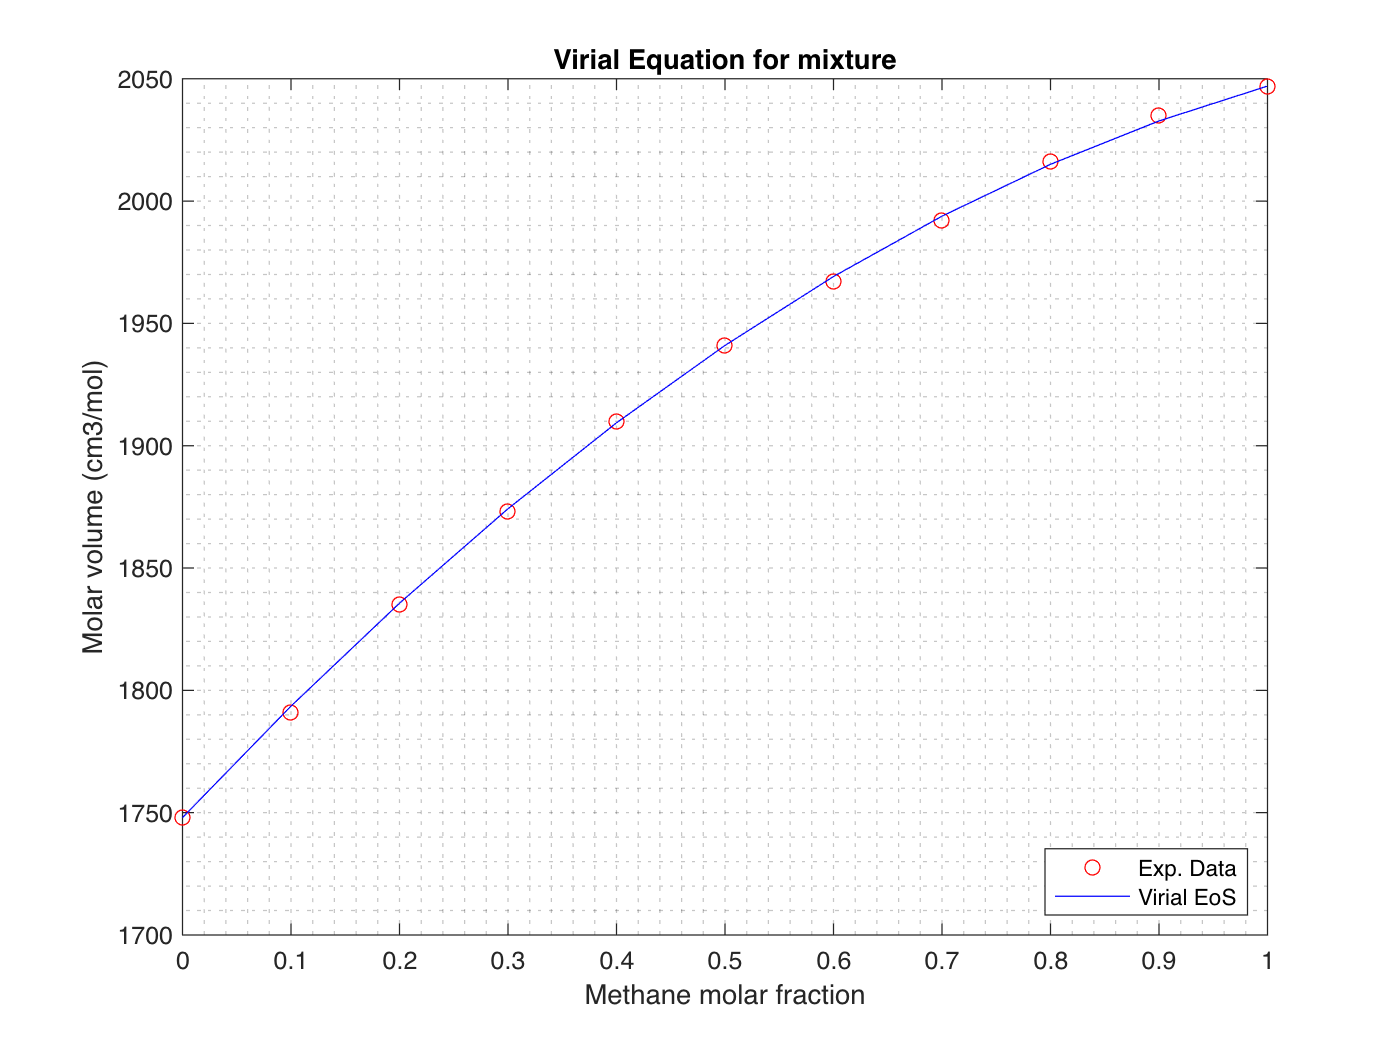

V_viriel = @(x) R*T/P*1000000 + B11.*(x).^2 + 2.*B12.*x.*(1-x) + B22.*(1-x).^2;
plot (x,V,'or');
grid minor
xlabel('Methane molar fraction')
ylabel('Molar volume (cm3/mol)')
title('Virial Equation for mixture')
hold on
x_id = x;
plot(x_id, V_viriel(x_id),'b')
legend('Exp. Data','Virial EoS','location','southeast')
hold off;

Quels commentaires pouvez-vous faire sur le choix de ce modèle ? 

## Détermination des volumes molaires partiels

En utilisant le fitting et la dérivation numérique on peut proposer une première solution ...

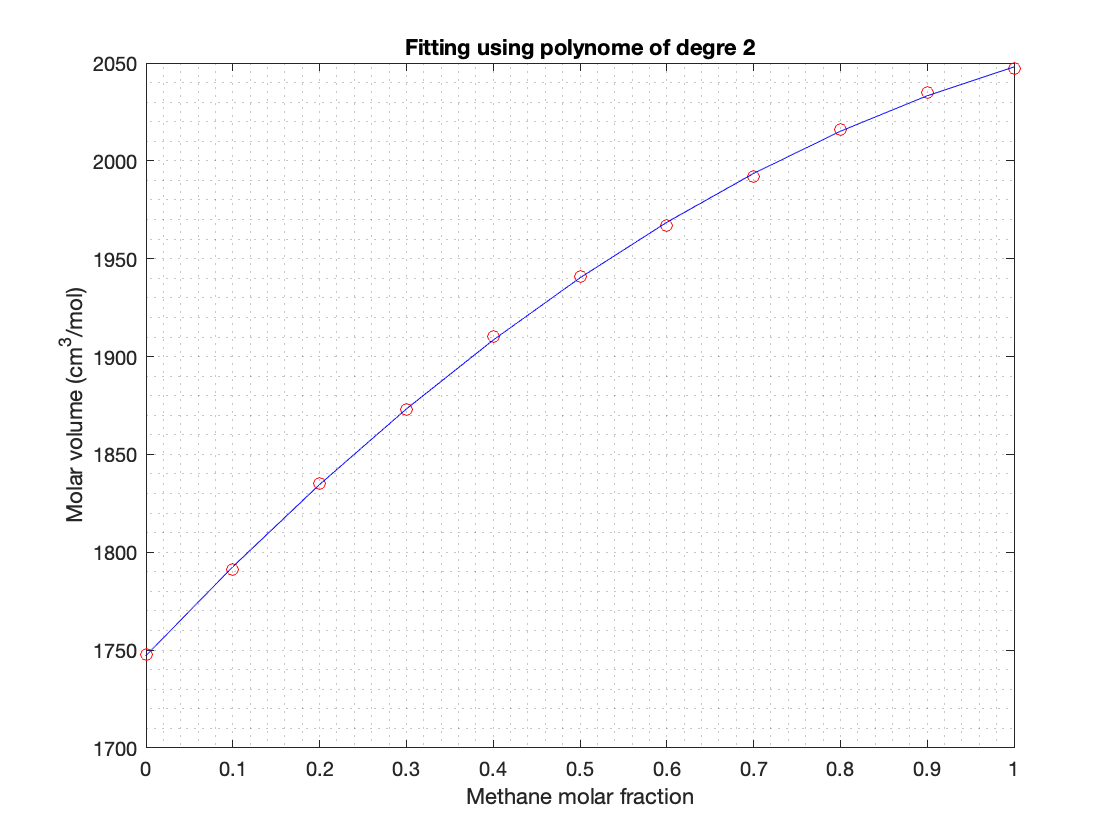

% fitting des points (x,V)  par un polynome du 2nd degre

Coeff = polyfit(x,V,2);
plot (x,V,'or');
hold on

grid minor
xlabel('Methane molar fraction')
ylabel('Molar volume (cm^3/mol)')
title('Fitting using polynome of degre 2')

plot (x_id, Coeff(1).*x_id.^2 + Coeff(2).*x_id +Coeff(3), 'b')
hold off; 

Le fitting est OK , on peut donc désormais calculer les volumes molaires partiels.

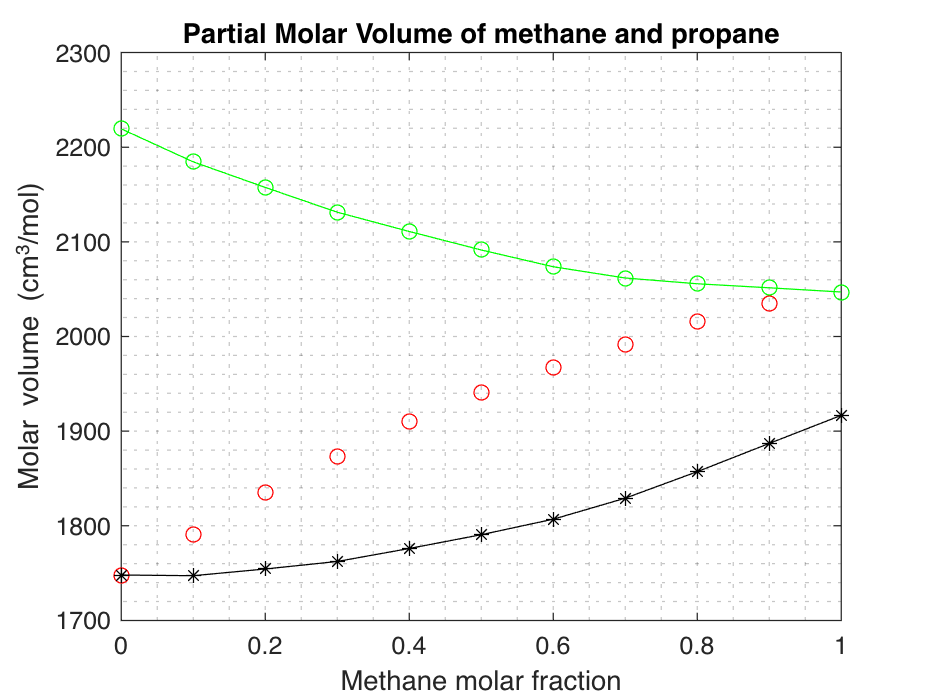

% calcul de la dérivée en un point 
alpha = 2*Coeff(1).*x + Coeff(2);

V1 = V - alpha.*(x-1);% partial molar volume of Methane
V2 = V - alpha.*x;% partial molar volume of Propane

plot (x,V,'or');
grid minor
xlabel('Methane molar fraction')
ylabel('Molar volume (cm^3/mol)')
title('Partial Molar Volume of methane and propane')
hold on

plot(x,V1,'go-')
plot(x,V2,'k*-')
hold off;

Application de la relation sur les volumes molaires partiels (5)

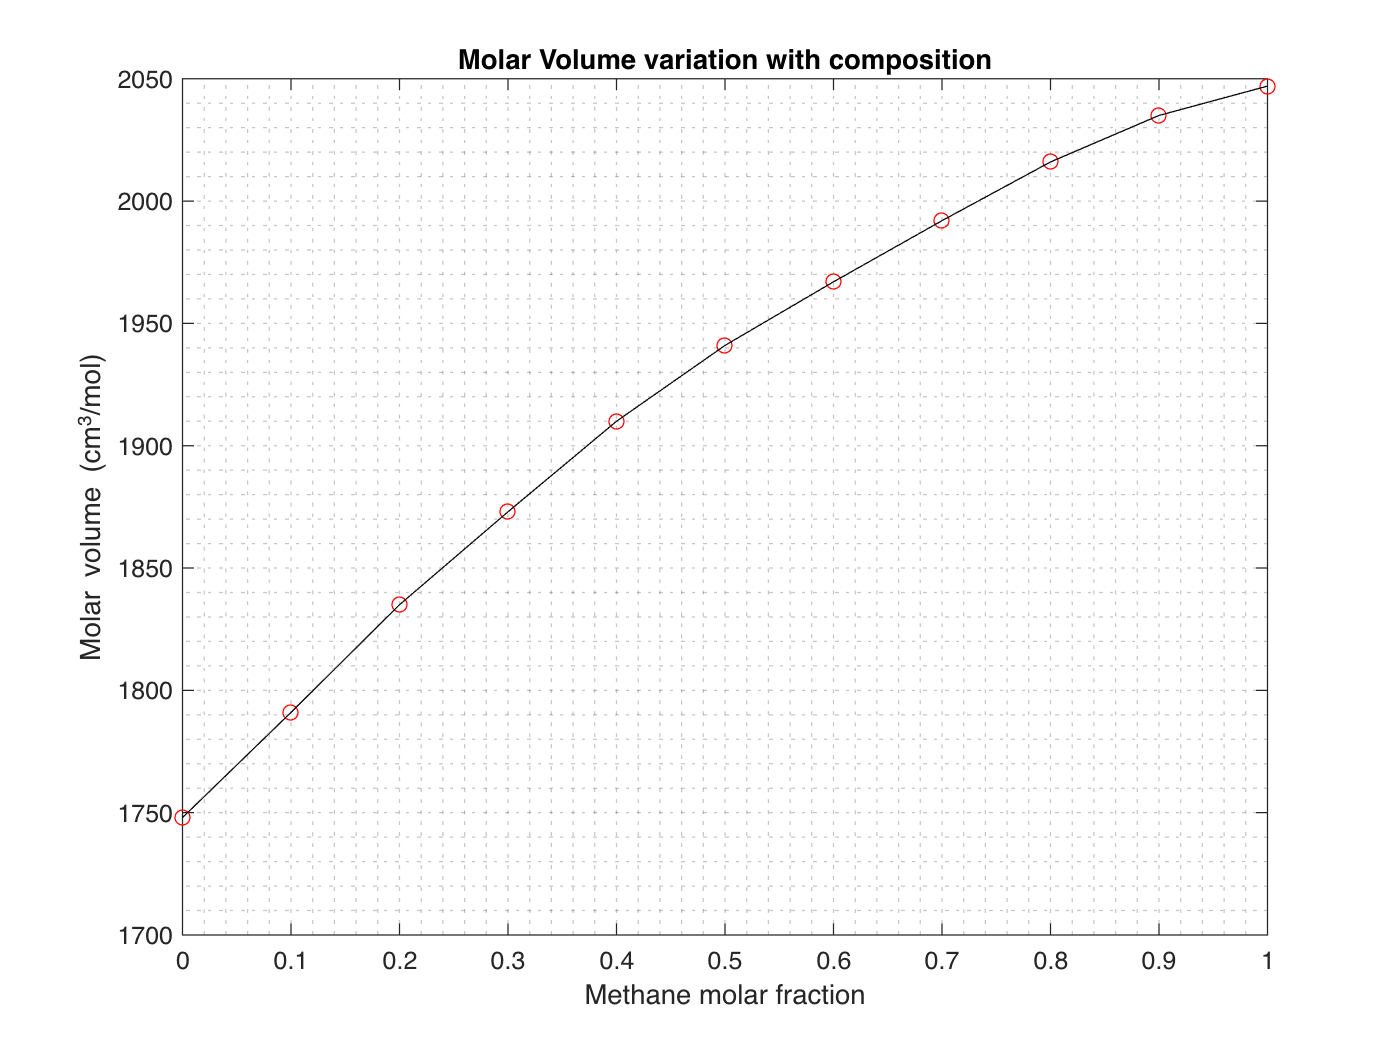

V_partial = x.*V1 + (1-x).*V2;
plot (x,V,'or');
grid minor
xlabel('Methane molar fraction')
ylabel('Molar volume (cm^3/mol)')
title('Molar Volume variation with composition')
hold on

plot(x,V_partial,'k-')
hold off;

## Calcul du volume molaire partiel "littérale"

A partir de l'expression (9), (11) et de $N_1$ et $N_2$ démontrer  que l'on a bien l'expression suivante pour les volumes molaires partiels

$\displaystyle \bar{v}_i = \left (\frac{\partial V}{\partial N_i} \right )_{P,T,Nj\neq i} = \frac{RT}{P}+2\sum_{j=1}^nB_{i,j}y_j - B$ (12)

Vérification avec les points obtenus : 

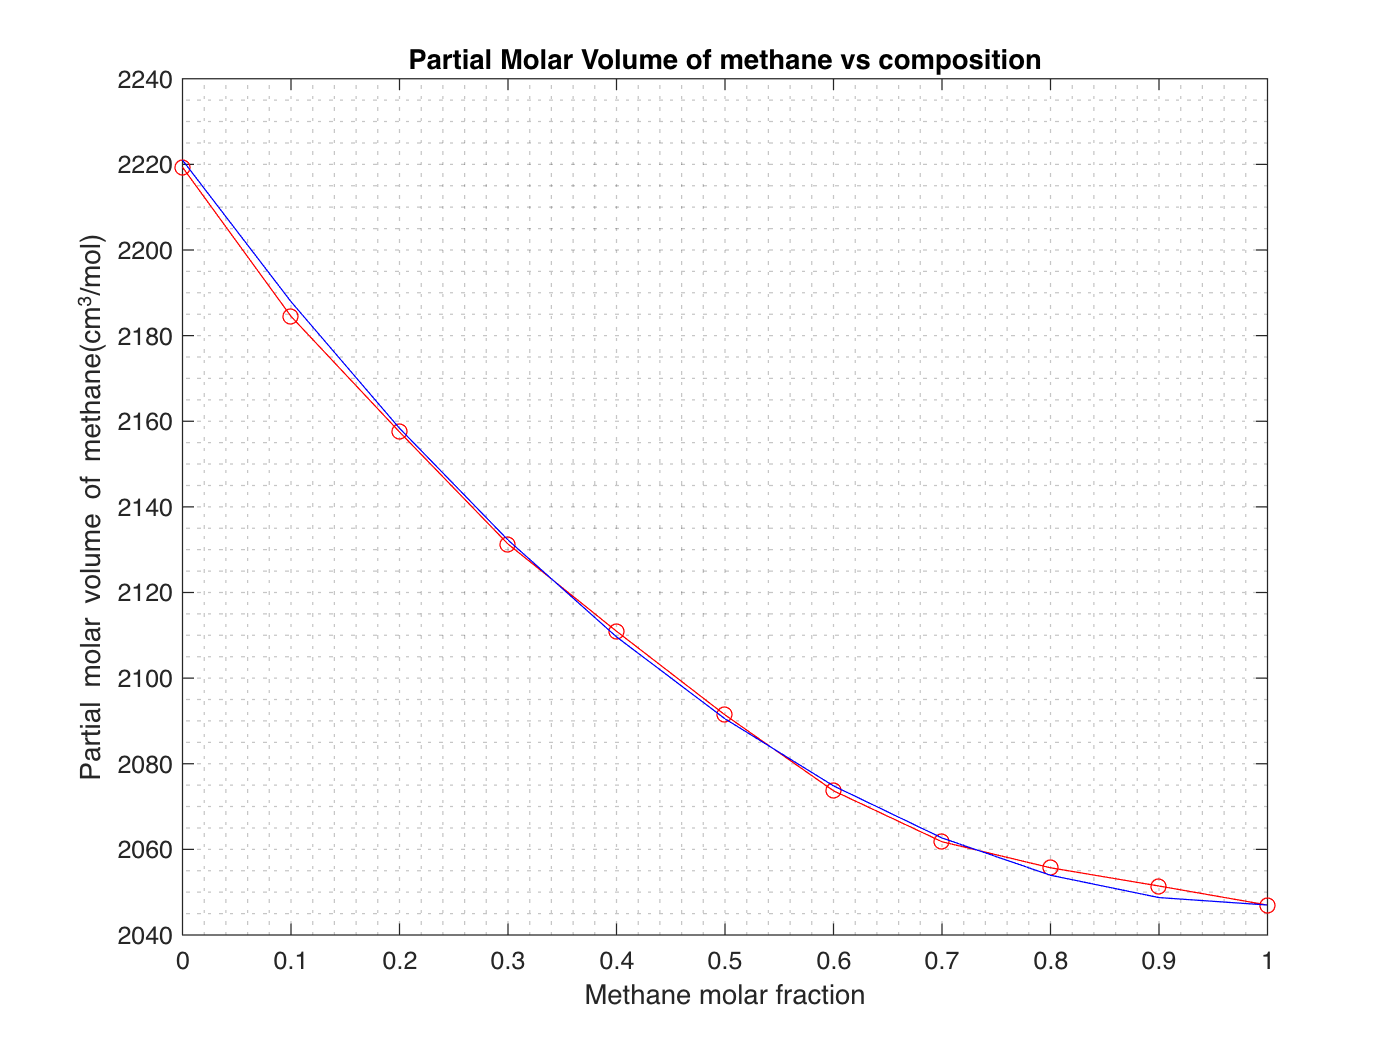

V1_viriel = @(x) R*T/P*1000*1000 + 2*(B11.*x + (1-x).*B12) - (B11.*x.^2 + 2*B12.*x.*(1-x)+B22.*(1-x).^2);

plot(x,V1,'ro-')
grid minor
xlabel('Methane molar fraction');
ylabel('Partial molar volume of methane(cm^3/mol)');
title('Partial Molar Volume of methane vs composition');
hold on
plot(x_id,V1_viriel(x_id),'b' )
hold off

## Calcul du volume de mélange

Si l'on considère que notre référence est un mélange idéal de gaz parfait, alors il est possible de calculer le volume de mélange comme étant : 

$V_{mel} = V - V_{mel}^{id}$ (13)

Nous avons noté que dans notre cas que le volume du mélange de gaz parfait sera toujours le même et donc : 

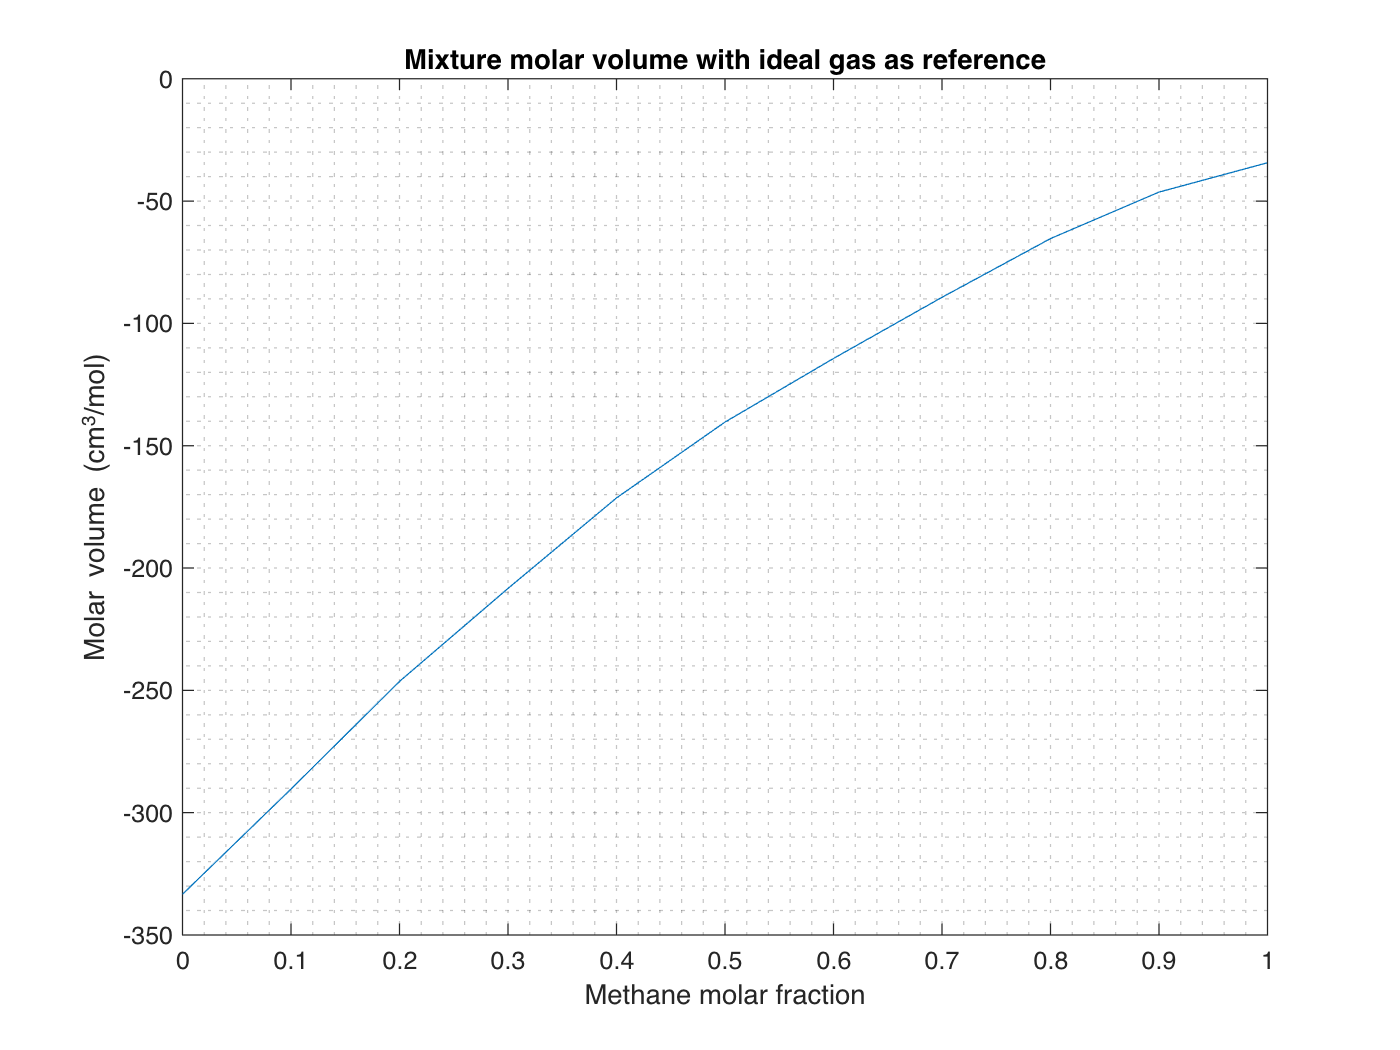

V_mel_GP = V - V_GP;
plot (x, V_mel_GP);
grid minor;
xlabel('Methane molar fraction');
ylabel('Molar volume (cm^3/mol)');
title('Mixture molar volume with ideal gas as reference');
hold off;

Si l'on considère que notre référence est un mélange idéal de gaz réel, alors son obtient : 

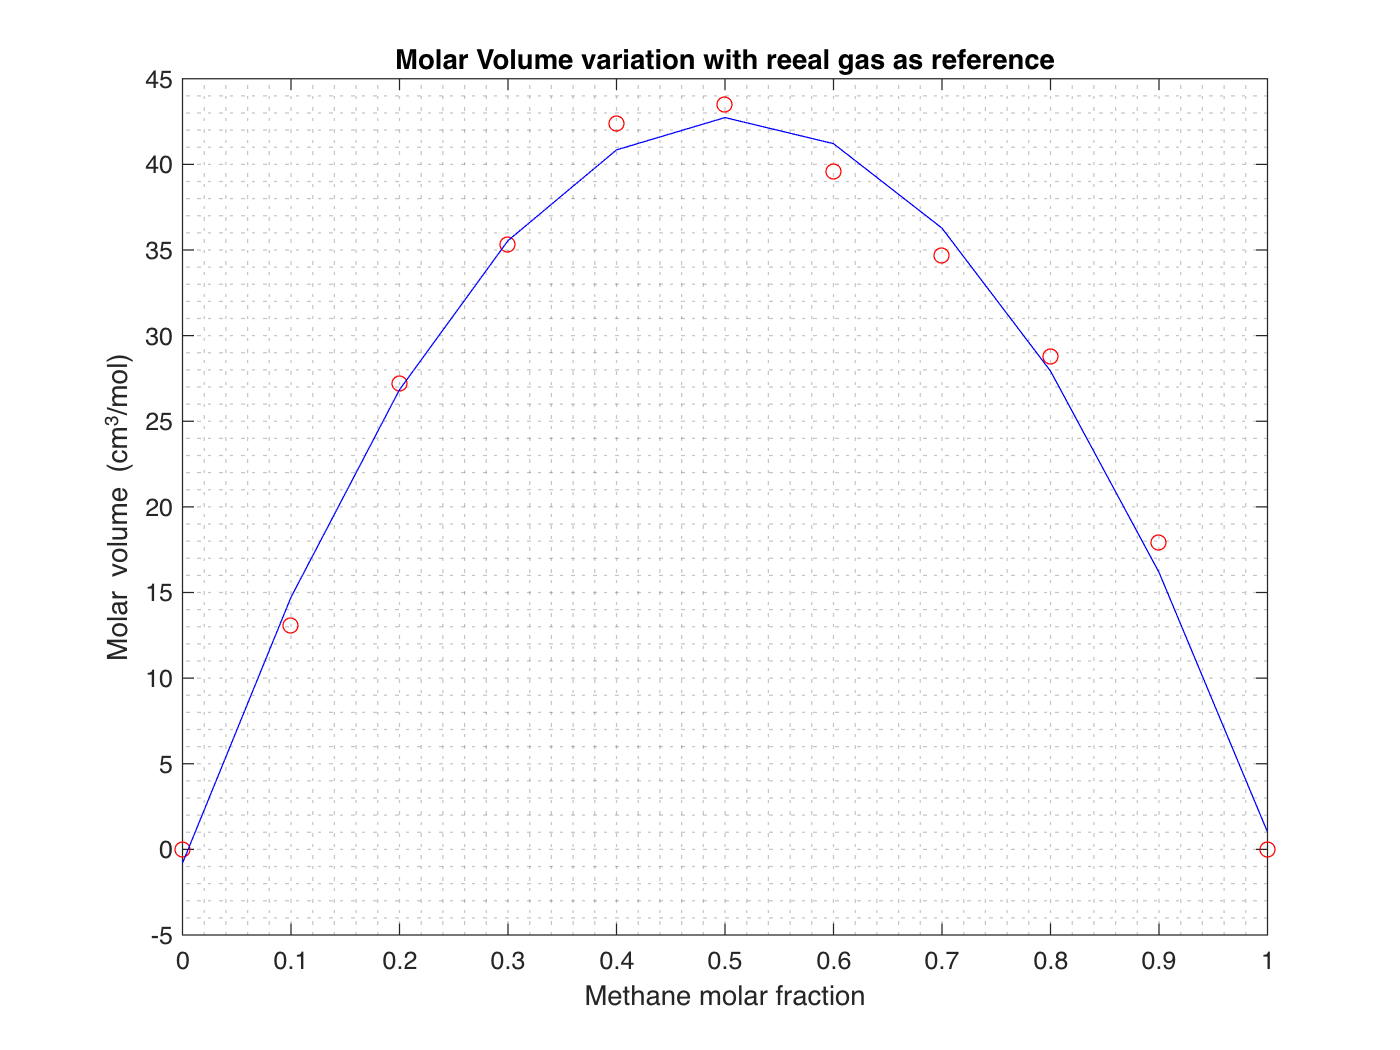


V_id = 2047.*x + (1-x).*1748;
V_mel_id = V - 2047.*x - (1-x).*1748;

plot (x, V_mel_id,'or')
hold on
Coeff2 = polyfit(x,V_mel_id,2);
plot(x_id, Coeff2(1).*x_id.^2 + Coeff2(2).*x_id+Coeff2(3),'b')
grid minor
xlabel('Methane molar fraction')
ylabel('Molar volume (cm^3/mol)')
title('Molar Volume variation with reeal gas as reference')
hold off

## Analyse graphique

A partir de l'ensemble des résultats obtenus précédement, présentez une visualisation graphique des volumes molaires partielles et de mélange, pour toute composition comprise  entre 0 et 1

 x_cal= 0.5;

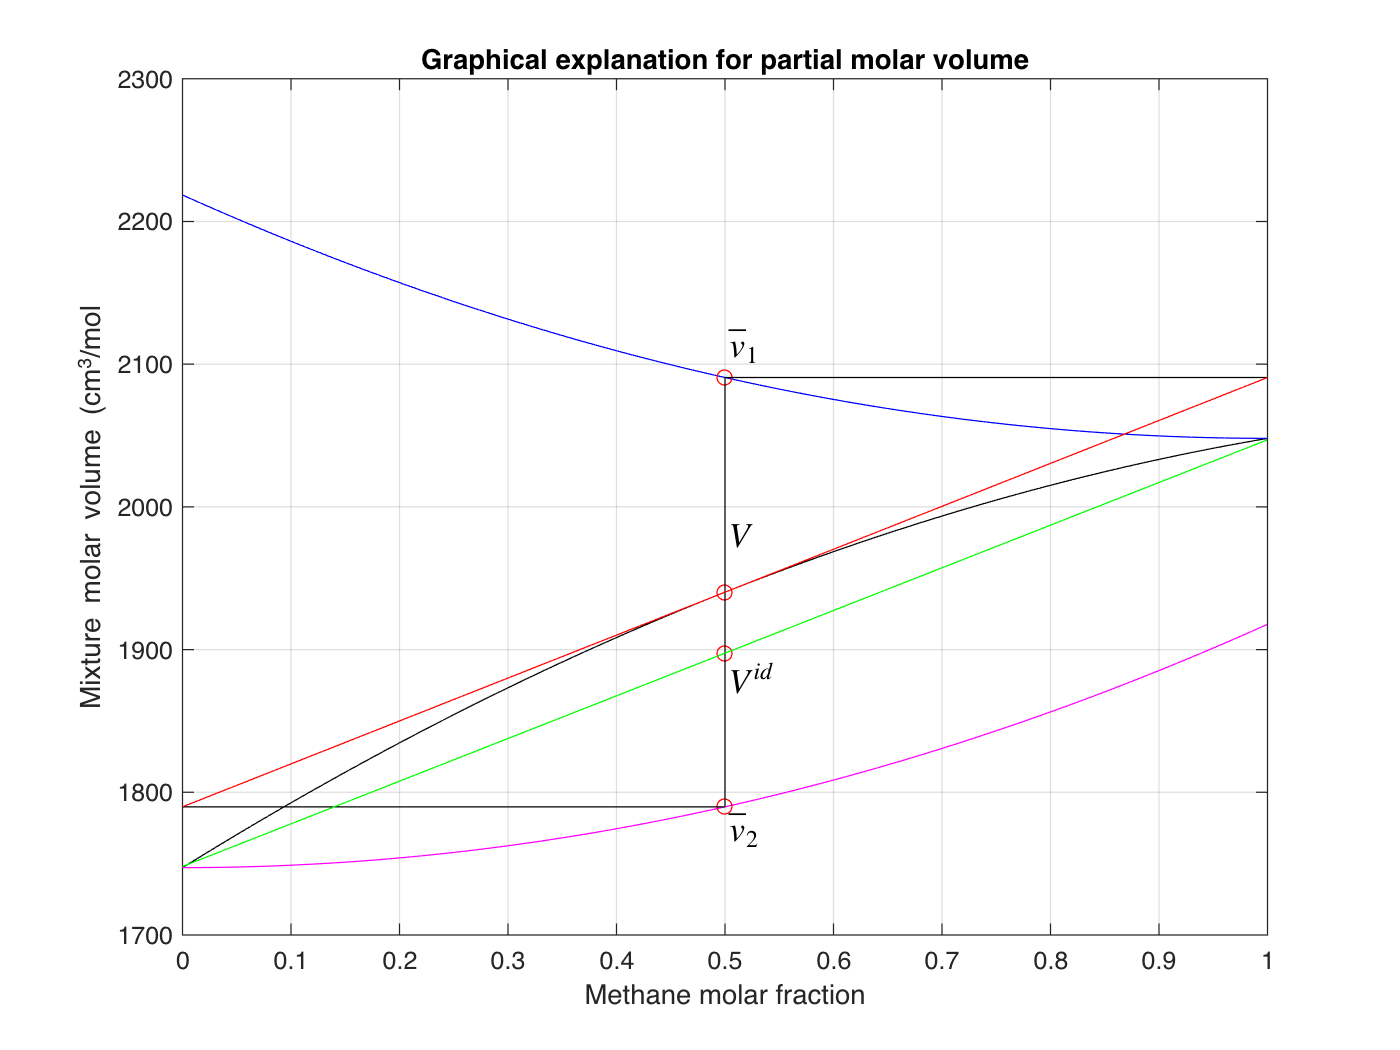

% fonction Volume du mélange 
f_mel = @(x) Coeff(1).*x.^2 + Coeff(2).*x +Coeff(3);
f_mel_id = @(x) V(end).*x + V(1).*(1-x);
% fonction Volume molaire partielle du methane
f_V1 = @(x) f_mel(x) - (2*Coeff(1).*x + Coeff(2)).*(x-1);
f_V2 = @(x) f_mel(x) - (2*Coeff(1).*x + Coeff(2)).*x;

% Tracé graphique

x_mel = 0:0.01:1;
plot(x_mel, f_mel(x_mel),'k')
grid minor;
xlabel('Methane molar fraction');
ylabel('Mixture molar volume (cm^3/mol');
title('Graphical explanation for partial molar volume');
hold on

plot(x_mel, f_V1(x_mel),'b');
plot(x_mel, f_V2(x_mel),'m');

% position des points spécifiques

plot(x_cal,f_mel(x_cal),'or'); plot(x_cal,f_V1(x_cal),'or');
plot(x_cal,f_V2(x_cal),'or'); plot(x_cal,f_mel_id(x_cal),'or');

% calcul des droites de tracé

plot([0 x_cal], [f_V2(x_cal) f_V2(x_cal)],'k-');
plot([x_cal 1], [f_V1(x_cal) f_V1(x_cal)],'k-');
plot([x_cal x_cal], [f_V1(x_cal) f_V2(x_cal)],'k-');

plot([0 1], [f_V2(x_cal) f_V1(x_cal)],'r');
plot([0 1],[V(1) V(end)],'g');
grid on; grid minor
hold off

% Text & formula
str_v1 = '$$\bar{v}_1$$'; str_v2 = '$$\bar{v}_2$$';
str_v_mel = '$$V$$';str_v_mel_id = '$$V^{id}$$';

text(x_cal,f_V2(x_cal)*0.99,str_v2,'Interpreter','latex','FontSize',14);
text(x_cal,f_V1(x_cal)*1.01,str_v1,'Interpreter','latex','FontSize',14);
text(x_cal,f_mel_id(x_cal)*0.99,str_v_mel_id,'Interpreter','latex','FontSize',14);
text(x_cal,f_mel(x_cal)*1.02,str_v_mel,'Interpreter','latex','FontSize',14);

## Utilisation de bibliothèque spécialisée

Le cas de CoolProp est intéressant car il prend en compte les EoS spécifiques de chaque composé, et propose des mélanges cohérents. Application à notre cas. Pour charger la librairie, consulter [Moodle : Outlis / MATLAB](https://moodle.centrale-marseille.fr/course/view.php?id=262) ou bien allez sur [CoolProp.org](https://sourceforge.net/projects/coolprop/files/CoolProp/6.1.0/MATLAB/). Nous utiliserons plus tard la librairie Simulis Thermodynamics plus complexe à manipuler cependant. 

#### Calcul du Volume molaire du méthane et du propane dans les conditions T,P. 

import py.CoolProp.CoolProp.* 

V_CH4_CoolProp = 1/PropsSI('DMOLAR','P',P,'T',T,'CH4') ;
fprintf('Volume molaire CoolProp du Méthane = %.2f cm3/mol \n',V_CH4_CoolProp*1E6);

Volume molaire CoolProp du Méthane = 2054.01 cm3/mol 


V_C3H8_CoolProp = 1/PropsSI('DMOLAR','P',P,'T',T,'C3H8') ;
fprintf('Volume molaire CoolProp du Propane = %.2f cm3/mol \n',V_C3H8_CoolProp*1E6);

Volume molaire CoolProp du Propane = 1756.41 cm3/mol 


#### Calcul du volume molaire du mélange : 

Les mélanges sont définis dans CoolProp comme suit : 

V_mel_CoolProp = 1/PropsSI('DMOLAR','T',T,'P',P,'Methane[0.5]&Propane[0.5]');
fprintf('Volume molaire (CoolProp) mélange équimolaire  = %.2f cm3/mol \n',V_mel_CoolProp*1E6);

Volume molaire (CoolProp) mélange équimolaire  = 1949.21 cm3/mol 


Application à notre mélange

i=1;
V_mel_CoolProp = zeros(101,1);

for y = 0:0.01:1
    Melange = ['CH4[' num2str(y) ']&C3H8[' num2str(1-y) ']'];
    V_mel_CoolProp(i) = 1/PropsSI('DMOLAR','P',P,'T',T,Melange)*1E6;
    i = i+1;
end
hold off

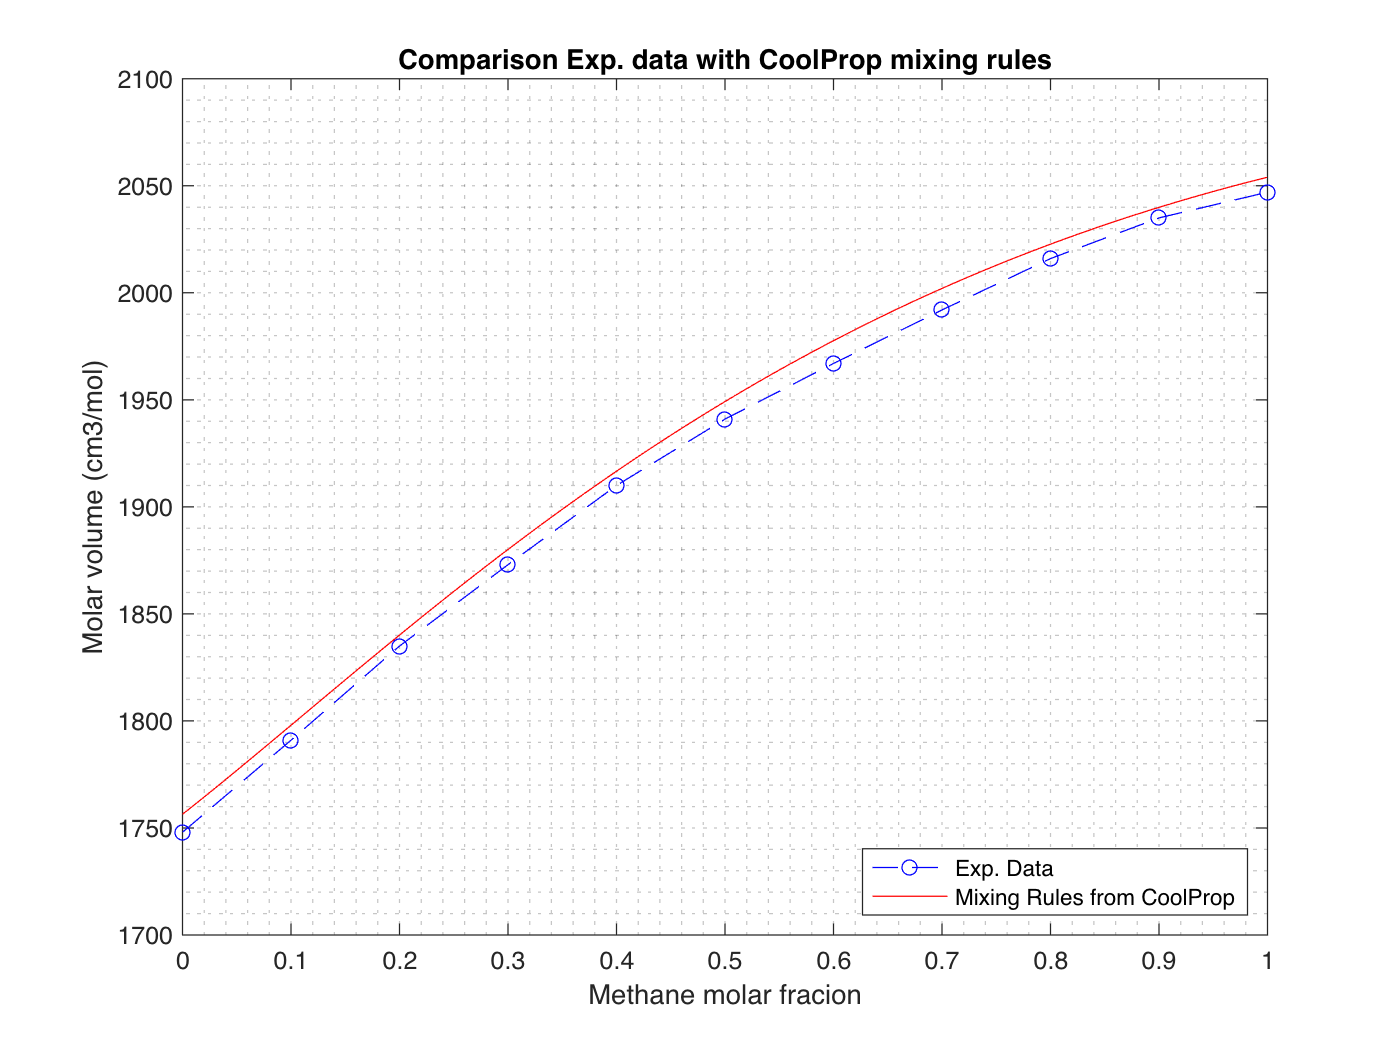

PLOT_Data = plot (x,V,'b--o');
hold on;
grid minor;
xlabel('Methane molar fracion');
ylabel('Molar volume (cm3/mol)');
title('Comparison Exp. data with CoolProp mixing rules');
PLOT_CoolProp = plot (0:0.01:1,V_mel_CoolProp,'r');
legend([PLOT_Data PLOT_CoolProp],'Exp. Data', 'Mixing Rules from CoolProp', 'Location','southeast')
hold off;

## Bibliographie 

[1] J. Vidal, Thermodynamique - Application au Génie Chimique et à l'industrie pétrolière, Editions TECHNIP, 1997.

[2] Poling, B., Prausnitz, J., & O' Connell, J. (2000). The Properties of Gases and Liquids. McGraw Hill Professional. 

[3] Haynes, W. M. (2016). CRC Handbook of Chemistry and Physics, 97th Edition. CRC Press.

## Fonctions 

Dans un live script, tout comme un script, les fonctions externes doivent être placées en fin de fichier. 

function B = Virial_B(T,C)
    T0 = 298.15; % ref Temperature [K]
    B = 0 ;
    for i = 1:1:size(C,2)
     B = B + C(i).*(T0./T-1).^(i-1);
    end
end